# Data Processing - Remove Regeneration - ARIMA 분석 - #5 #6을 사용하자

clear % 이전 그래프는 지우지 않는다.
close all %  이전 그래프는 지운다.
load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat

cap05 = extract_discharge(B0005);
cap06 = extract_discharge(B0006);
cap07 = extract_discharge(B0007);
cap18 = extract_discharge(B0018);


%result = [cap',cycleTimeHour',restTimeHour',restCycle',cCCEndTimeSec',cTempMaxDt',cCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',dTempMaxDt',dCcEndTimeSec' ];
%result = [cap',cycleTimeHourHour',restTimeHourHour',restCycle',cTempMax',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe',dTempMax',cCcEndTimeSec',dCcEndTimeSec' ];
%result = [cap',cycleTimeHour',restTimeHour',restCycle',cTempMax',cCcEndTimeSec',dTempMax',dCcEndTimeSec',ohm',re_c',re_d',cycleNoChargeRe',cycleNoDischargeRe' ];

i=1;
capacityIdx = i; i=i+1;
cycleTimeHourIdx = i; i=i+1;
restTimeHourIdx = i; i=i+1;
restCycleIdx = i; i=i+1;
cTempMaxIdx = i; i=i+1;
cCcEndTimeSecIdx = i; i=i+1;
dTempMaxIdx = i; i=i+1;
dCcEndTimeSecIdx = i; i=i+1;
ohmIdx = i; i=i+1;
re_cIdx = i; i=i+1;
re_dIdx = i; i=i+1;
cycleNoChageReIdx = i; i=i+1;
cycleNoDischageReIdx = i; i=i+1;
pattern_dVoltIdx = i; i=i+1;
pattern_tempdx = i; i=i+1;
pattern_CC_ampsIdx = i; i=i+1;

pattern_temp05_const = 24;
pattern_temp06_const = 24;
pattern_temp07_const = 24;
pattern_temp18_const = 24;


pattern_CC_amps05_const = 2;
pattern_CC_amps06_const = 2;
pattern_CC_amps07_const = 2;
pattern_CC_amps18_const = 2;


pattern_dVolt05_const = 4.2 - 2.7 ; 
pattern_dVolt06_const = 4.2 - 2.5 ; 
pattern_dVolt07_const = 4.2 - 2.2 ; 
pattern_dVolt18_const = 4.2 - 2.5 ; 




result_05 = extract_feature_all_v2(B0005,0,cap05);
result_06 = extract_feature_all_v2(B0006,0,cap06);
result_07 = extract_feature_all_v2(B0007,0,cap07);
result_18 = extract_feature_all_v2(B0018,0,cap18);




pattern_dVolt_vector   = ones(length(result_05),1) *  pattern_dVolt05_const; result_05 = [result_05,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_06),1) *  pattern_dVolt06_const; result_06 = [result_06,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_07),1) *  pattern_dVolt07_const; result_07 = [result_07,pattern_dVolt_vector];
pattern_dVolt_vector   = ones(length(result_18),1) *  pattern_dVolt18_const; result_18 = [result_18,pattern_dVolt_vector];

pattern_temp_vector   = ones(length(result_05),1) *  pattern_temp05_const; result_05 = [result_05,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_06),1) *  pattern_temp06_const; result_06 = [result_06,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_07),1) *  pattern_temp07_const; result_07 = [result_07,pattern_temp_vector];
pattern_temp_vector   = ones(length(result_18),1) *  pattern_temp18_const; result_18 = [result_18,pattern_temp_vector];


pattern_CC_amps_vector   = ones(length(result_05),1) *  pattern_CC_amps05_const; result_05 = [result_05,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_06),1) *  pattern_CC_amps06_const; result_06 = [result_06,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_07),1) *  pattern_CC_amps07_const; result_07 = [result_07,pattern_CC_amps_vector];
pattern_CC_amps_vector   = ones(length(result_18),1) *  pattern_CC_amps18_const; result_18 = [result_18,pattern_CC_amps_vector];

%% remove rest cycle 
restCycleTF_raw_index = find (result_05(:,restCycleIdx) == 1 )'; result_05(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_06(:,restCycleIdx) == 1 )'; result_06(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_07(:,restCycleIdx) == 1 )'; result_07(restCycleTF_raw_index,:)=[];
restCycleTF_raw_index = find (result_18(:,restCycleIdx) == 1 )'; result_18(restCycleTF_raw_index,:)=[];

               
i = 1;
capacity05 = result_05(:,i); 
capacity06 = result_06(:,i); 
capacity07 = result_07(:,i); 
capacity18 = result_18(:,i); 


% base is 2V 
capacityNorm05 = result_05(:,i) + 2 - result_05(1,i); 
capacityNorm06 = result_06(:,i) + 2 - result_06(1,i); 
capacityNorm07 = result_07(:,i) + 2 - result_07(1,i); 
capacityNorm18 = result_18(:,i) + 2 - result_18(1,i); 


i =  i + 1;
cycleTimeHour05 = result_05(:,i); 
cycleTimeHour06 = result_06(:,i); 
cycleTimeHour07 = result_07(:,i); 
cycleTimeHour18 = result_18(:,i); 


i =  i + 1;
restTimeHour05 = result_05(:,i); 
restTimeHour06 = result_06(:,i); 
restTimeHour07 = result_07(:,i); 
restTimeHour18 = result_18(:,i); 


i =  i + 1;
restCycle05 = result_05(:,i); 
restCycle06 = result_06(:,i); 
restCycle07 = result_07(:,i); 
restCycle18 = result_18(:,i); 


i =  i + 1;
cTempMax05 = result_05(:,i); 
cTempMax06 = result_06(:,i); 
cTempMax07 = result_07(:,i); 
cTempMax18 = result_18(:,i); 


i =  i + 1;
cCcEndTimeSec05 = result_05(:,i); 
cCcEndTimeSec06 = result_06(:,i); 
cCcEndTimeSec07 = result_07(:,i); 
cCcEndTimeSec18 = result_18(:,i); 


i =  i + 1;
dTempMax05 = result_05(:,i); 
dTempMax06 = result_06(:,i); 
dTempMax07 = result_07(:,i); 
dTempMax18 = result_18(:,i); 


i =  i + 1;
dCcEndTimeSec05 = result_05(:,i); 
dCcEndTimeSec06 = result_06(:,i); 
dCcEndTimeSec07 = result_07(:,i); 
dCcEndTimeSec18 = result_18(:,i); 


i =  i + 1;
ohm05 = result_05(:,i); 
ohm06 = result_06(:,i); 
ohm07 = result_07(:,i); 
ohm18 = result_18(:,i); 


i =  i + 1;
re_c05 = result_05(:,i); 
re_c06 = result_06(:,i); 
re_c07 = result_07(:,i); 
re_c18 = result_18(:,i); 



i =  i + 1;
re_d05 = result_05(:,i); 
re_d06 = result_06(:,i); 
re_d07 = result_07(:,i); 
re_d18 = result_18(:,i); 


i =  i + 1;
cycleNoChageRe05 = result_05(:,i); 
cycleNoChageRe06 = result_06(:,i); 
cycleNoChageRe07 = result_07(:,i); 
cycleNoChageRe18 = result_18(:,i); 


i =  i + 1;
cycleNoDischageRe05 = result_05(:,i); 
cycleNoDischageRe06 = result_06(:,i); 
cycleNoDischageRe07 = result_07(:,i); 
cycleNoDischageRe18 = result_18(:,i); 



i =  i + 1;
pattern_dVolt05 = result_05(:,i); 
pattern_dVolt06 = result_06(:,i); 
pattern_dVolt07 = result_07(:,i); 
pattern_dVolt18 = result_18(:,i); 


i =  i + 1;
pattern_temp05 = result_05(:,i); 
pattern_temp06 = result_06(:,i); 
pattern_temp07 = result_07(:,i); 
pattern_temp18 = result_18(:,i); 


i =  i + 1;
pattern_CC_amps05 = result_05(:,i); 
pattern_CC_amps06 = result_06(:,i); 
pattern_CC_amps07 = result_07(:,i); 
pattern_CC_amps18 = result_18(:,i); 



% https://kr.mathworks.com/matlabcentral/answers/269056-how-to-initialize-a-row-vector-with-value-zero-of-size-1xn
% https://kr.mathworks.com/matlabcentral/answers/105768-how-can-i-delete-certain-rows-of-a-matrix-based-on-specific-column-values


%{
% gen
% 58 53
% new data set #01 / #02
result_05(58,1)
result_06(53,1)

% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:58,:) ; result_06(:,53:end) ];
result_06_05 = [ result_06(1:53,:) ; result_05(:,58:end) ];
result_05_06_all = [ result_05 ; result_06 ];
%}

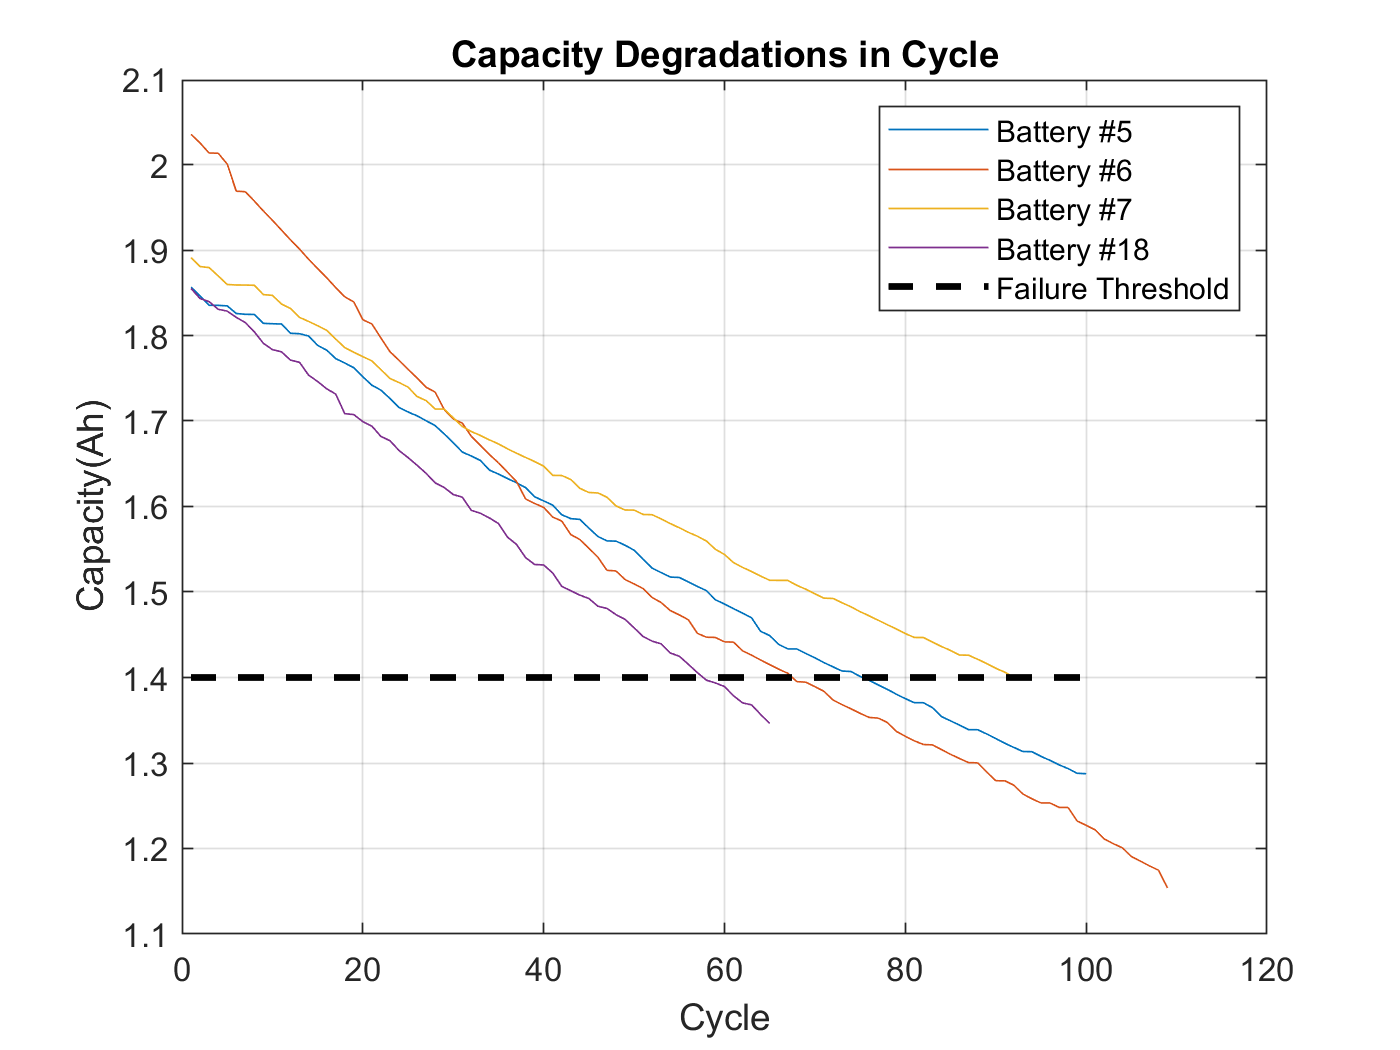

%% org graph - cycle
cycle_number = length(capacity05);

figure
plot(capacity05), hold on, plot(capacity06), plot(capacity07), plot(capacity18)
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #7', 'Battery #18','Failure Threshold')
title('Capacity Degradations in Cycle')

% modify ohm   20 -> 30
result_05(1:30,ohmIdx) = nan;
result_06(1:30,ohmIdx) = nan;
% no gen
% 27 30
% new data set #01 / #02
result_05(27,1)

ans = 1.7003

result_06(30,1)

ans = 1.7024

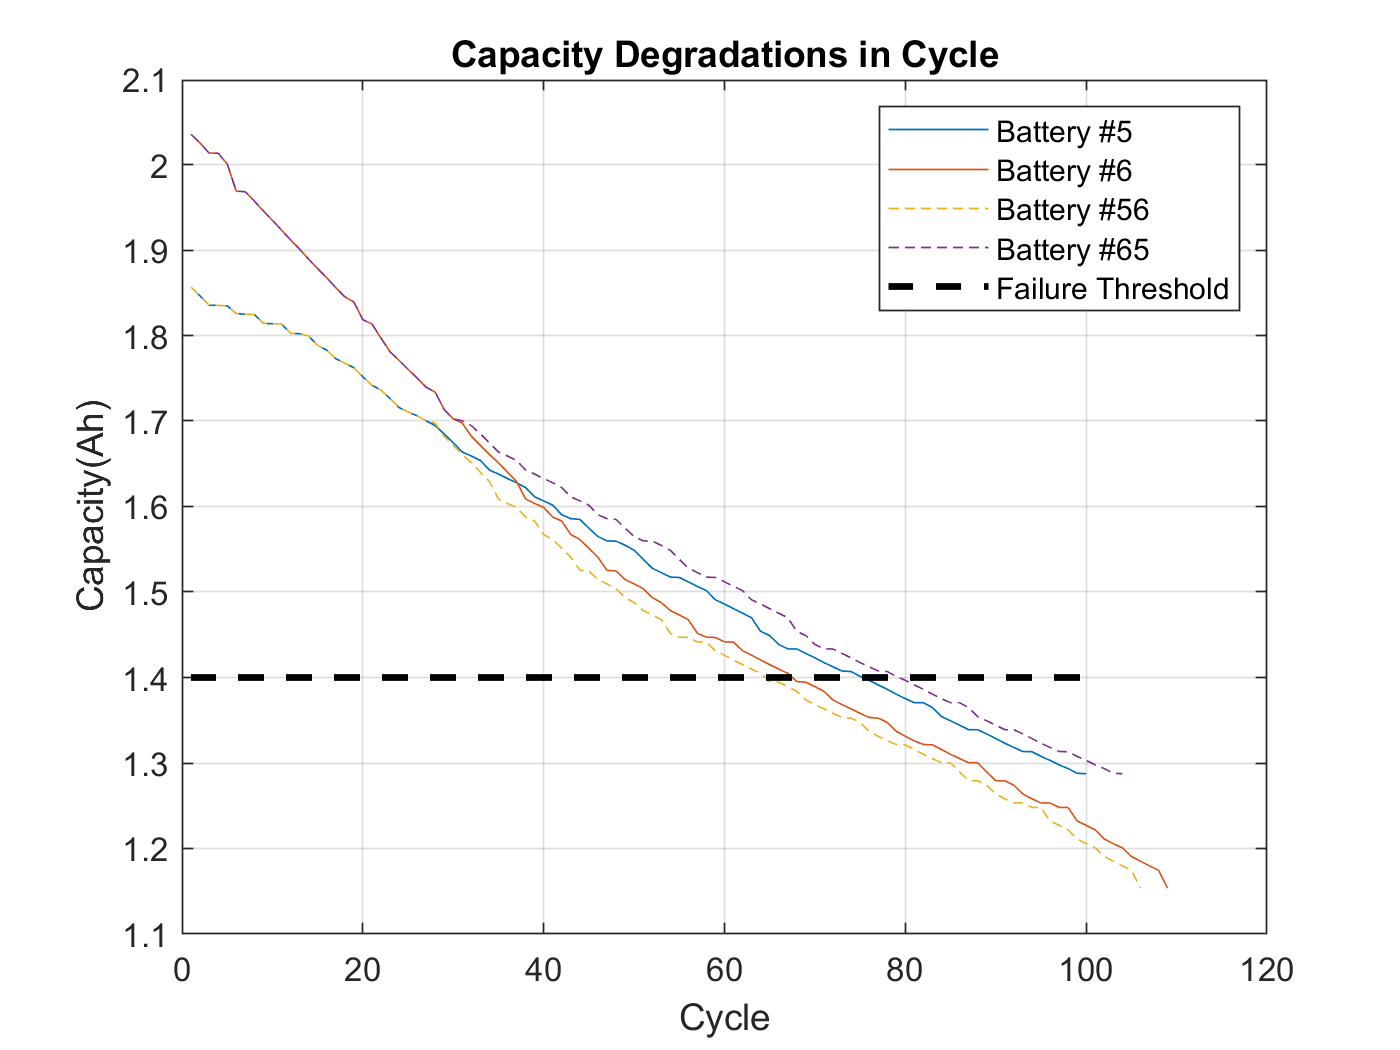


% ignore rest time , maxTempDt 
result_05_06 = [ result_05(1:27,:) ; result_06(31:end,:) ]; % 30 -> 31
result_06_05 = [ result_06(1:30,:) ; result_05(27:end,:) ];
result_05_06_patten_change = [27 31];
result_06_05_patten_change = [30 27];

result_05_06_all = [ result_05 ; result_06 ];
capacity56 = result_05_06(:,1);
capacity65 = result_06_05(:,1);
capacity_all = result_05_06_all(:,1);

%% org graph - cycle
cycle_number = length(capacity05);

figure
plot(capacity05), hold on, plot(capacity06), plot(capacity56,'--'), plot(capacity65,'--')
plot(1:cycle_number, 1.4*ones(1, cycle_number),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5', 'Battery #6', 'Battery #56', 'Battery #65','Failure Threshold')
title('Capacity Degradations in Cycle')


%% create vector / table
    
regression_vector_05 = [ ...
    result_05(:, cCcEndTimeSecIdx ) ...
    result_05(:, pattern_dVoltIdx ) ...
    result_05(:, capacityIdx ) ] ;

regression_vector_06 = [ ...
    result_06(:, cCcEndTimeSecIdx ) ...
    result_06(:, pattern_dVoltIdx ) ...
    result_06(:, capacityIdx ) ] ;


regression_vector_05_06_all = [ ...
    result_05_06_all(:, cCcEndTimeSecIdx ) ...
    result_05_06_all(:, pattern_dVoltIdx ) ...
    result_05_06_all(:, capacityIdx ) ] ;

regression_vector_05_06 = [ ...
    result_05_06(:, cCcEndTimeSecIdx ) ...
    result_05_06(:, pattern_dVoltIdx ) ...
    result_05_06(:, capacityIdx ) ] ;

regression_vector_06_05 = [ ...
    result_06_05(:, cCcEndTimeSecIdx ) ...
    result_06_05(:, pattern_dVoltIdx ) ...
    result_06_05(:, capacityIdx ) ] ;

% works
regression_table_05 = array2table(regression_vector_05,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_06 = array2table(regression_vector_06,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_05_06 = array2table(regression_vector_05_06,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_06_05 = array2table(regression_vector_06_05,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

regression_table_05_06_all = array2table(regression_vector_05_06_all,...
    'VariableNames',{'cCcEndTimeSec','pattern_dVolt','capacity'});

    
% https://kr.mathworks.com/help/matlab/ref/cell2table.html    
% works
%{
regression_table_5 = array2table(regression_vector_05,...
    'VariableNames',{'cCcEndTimeSec','capacity'});

regression_table_6 = array2table(regression_vector_06,...
    'VariableNames',{'cCcEndTimeSec','capacity'});
%}


% https://people.duke.edu/~rnau/arimrule.htm
% https://github.com/KevinChngJY/timeseriesinmatlab

% https://kr.mathworks.com/help/econ/specify-ar-models.html
X5 = regression_vector_05(:,1);
X5 = X5./1200 ; % sec to hour
Y5 = regression_vector_05(:,3);
U5 = regression_vector_05(:,2);

Y6 = regression_vector_06(:,3);
U6 = regression_vector_06(:,2);

Y56 = regression_vector_05_06(:,3);
U56 = regression_vector_05_06(:,2);

Y65 = regression_vector_06_05(:,3);
U65 = regression_vector_06_05(:,2);

# 가우시안 프로세스 

# Compare Prediction Intervals of GPR Models

This example fits GPR models to a noise-free data set and a noisy data set. The example compares the predicted responses and prediction intervals of the two fitted GPR models. 

Generate two observation data sets from the function $g\left(x\right)=x\cdot \sin \left(x\right)$. 

%result_05_06_patten_change = [27 31];
%result_06_05_patten_change = [30 27];

%{
BAT = Y56;
BAT_NAME = 'Y56';
pattern_change_index =27;

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;

BAT = Y5;
BAT_NAME = 'Y5';
pattern_change_index =30;

BAT = Y6;
BAT_NAME = 'Y6';
pattern_change_index =30;

%}

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;



%learning_start_index = 1;
learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = true;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

if use_just_observed
    % 변화된 구간 조금만 훈력
    x_observed = idxpre';
    y_observed1 =  BAT(idxpre);    
else
    % 모든 구간에 대해 훈련
    x_observed = idxall';
    y_observed1 =  BAT(idxall);   
end

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));


The values in `y_observed1` are noise free, and the values in `y_observed2` include some random noise. 

Fit GPR models to the observed data sets.

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
%}

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );




Compute the predicted responses and 95% prediction intervals using the fitted models. 

[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');


Resize a figure to display two plots in one figure.

fig = figure;
fig.Position(3) = fig.Position(3)*2;

Create a 1-by-2 tiled chart layout.

tiledlayout(1,2,'TileSpacing','compact')

For each tile, draw a scatter plot of observed data points and a function plot of $x\cdot \sin \left(x\right)$. Then add a plot of GP predicted responses and a patch of prediction intervals. 

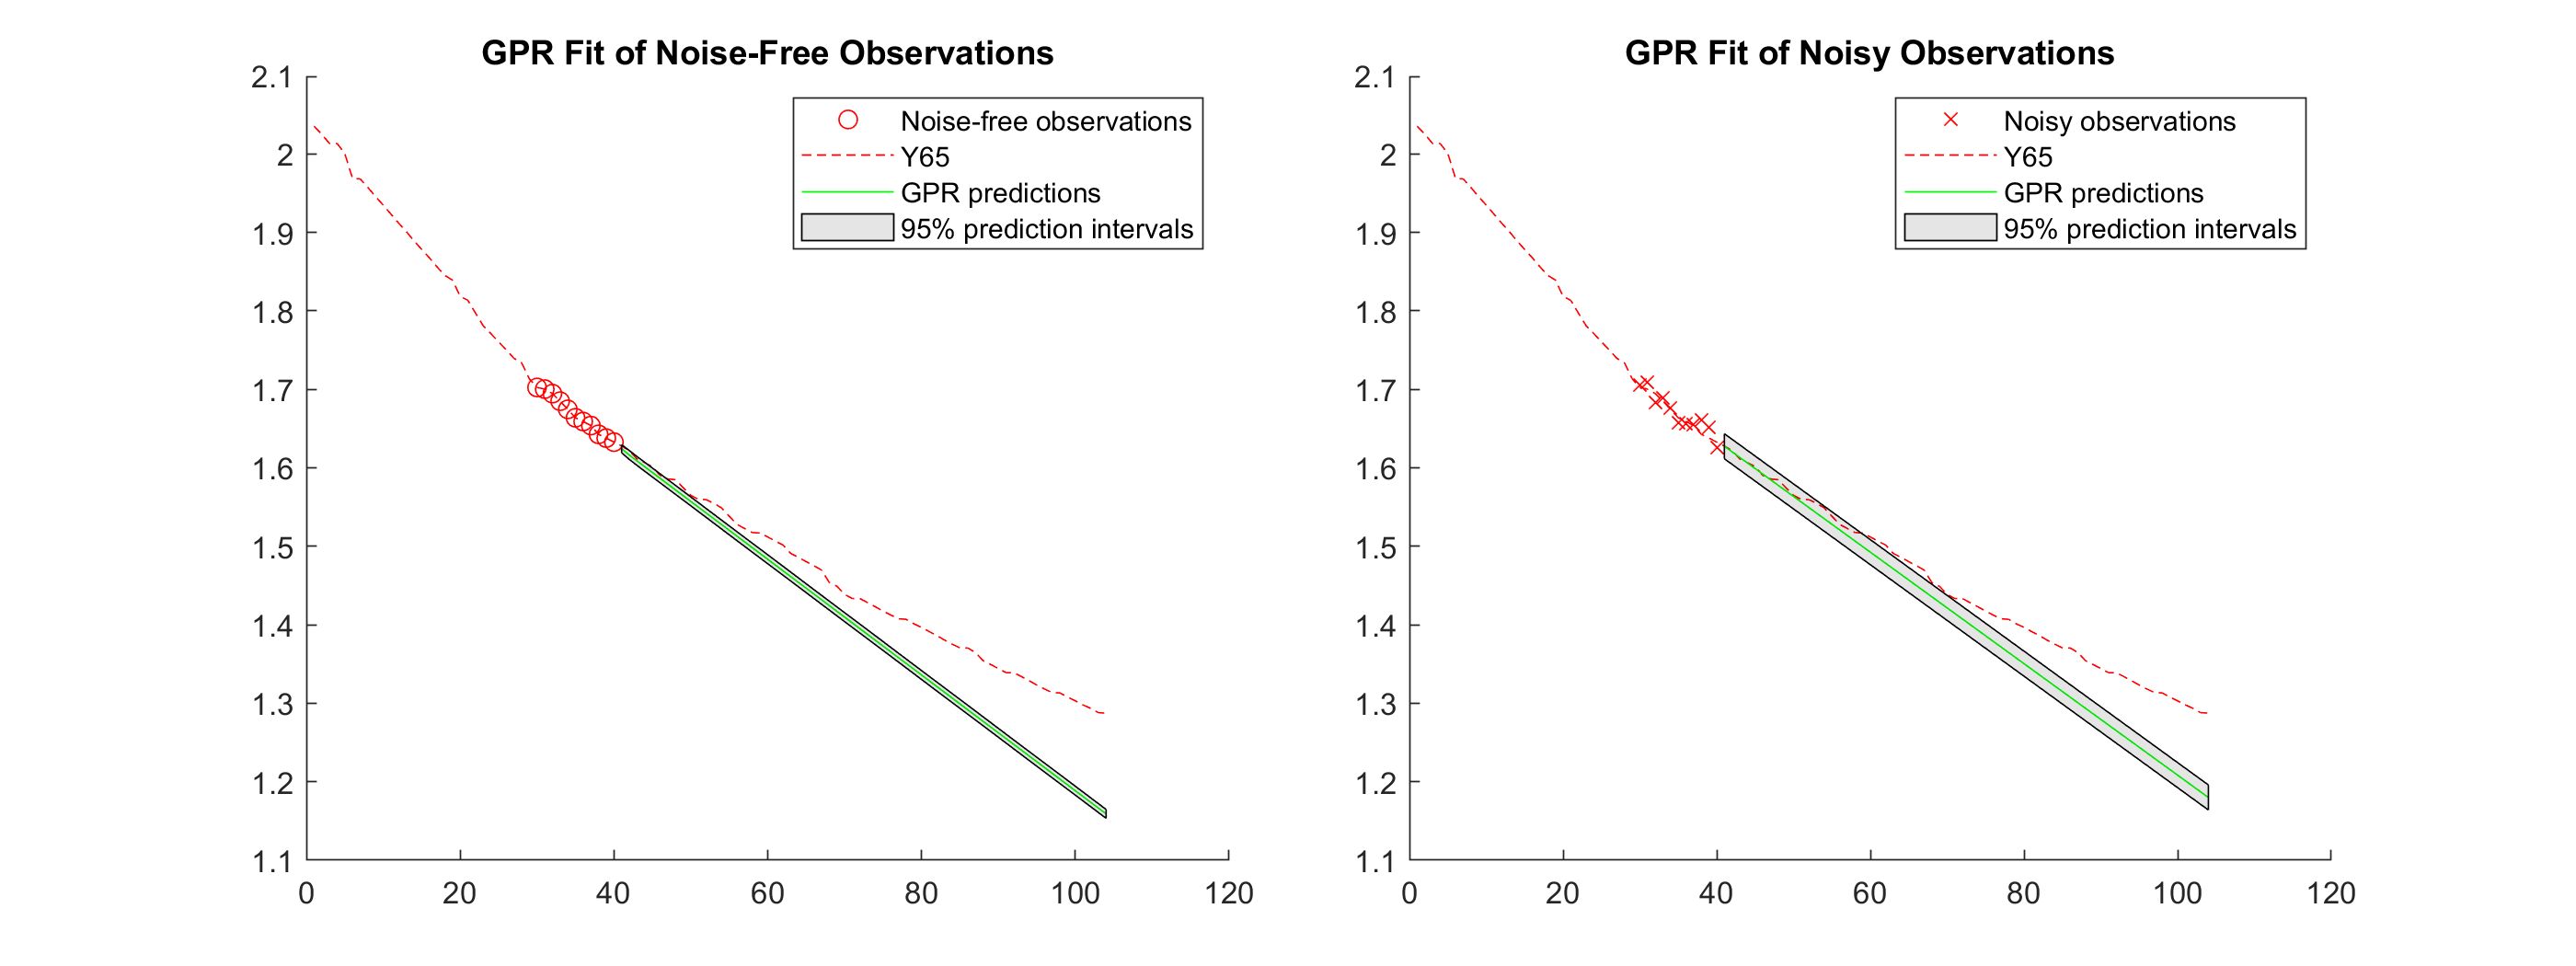

nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

GP 로는 잘 동작하지 않는다.

mean function 이 정확해야 하나 패넡 변화를 인지하더라도 mean function 이 선형적이 아니라서 결국 예측에 실패한다.

따라서 GP는 패턴별로 여러 데이타셋을 가지고 테스트 해야 의미가 있는 것 같다. 

change point들을 계속 검색하고

선형 회귀의 가중치를 이전의 측정값에 가중치를 줄이고 

최근 변화된 데이타를 가중치를 더 주면 

GP를 사요할 경우 계속 추정치가 현실에 맞게 변화될 것이다.

이는 Kalman Filter랑 비슷하다.

여기서 평가는 학습구간과 예측구간이 점차 뒤로 이동하게 된다.

이에 따른 평가를 해야 한다.

다시 보면 이는 LSTM 이라 같은 결과를 가져올 것 같다. 

관측값을 처음부터  패턴 변경 후 10번째 까지로 하자

learning_start_index = 1;

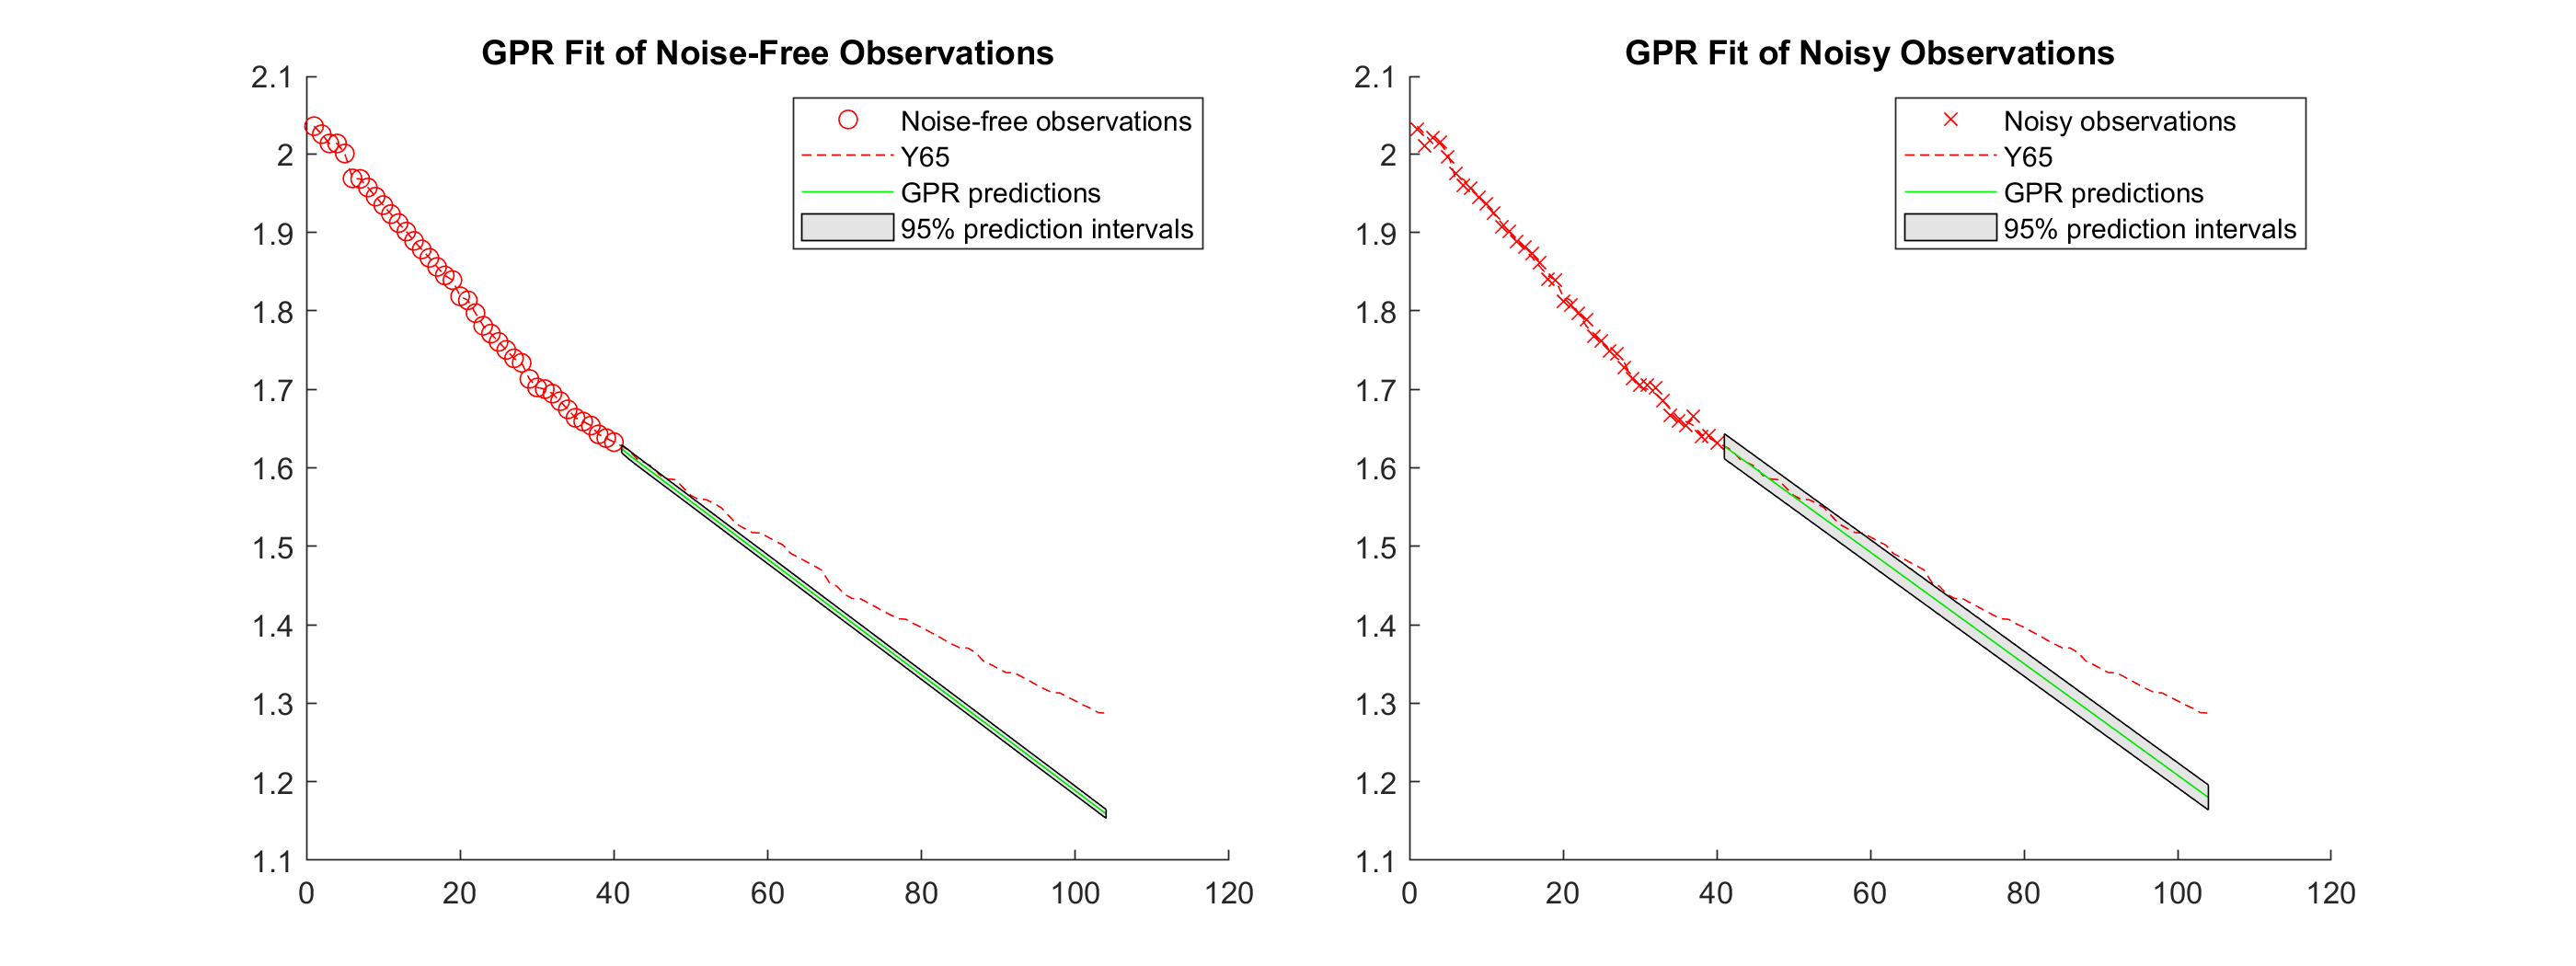

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;

learning_start_index = 1;
%learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = true;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

if use_just_observed
    % 변화된 구간 조금만 훈력
    x_observed = idxpre';
    y_observed1 =  BAT(idxpre);    
else
    % 모든 구간에 대해 훈련
    x_observed = idxall';
    y_observed1 =  BAT(idxall);   
end

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
%}

%{
gprMdl1 = fitrgp(x_observed,y_observed1,"Basis","constant","KernelFunction" , "squaredexponential" , ...
    'OptimizeHyperparameters','auto',"FitMethod" , "exact" , "PredictMethod" , "exact" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"Basis","constant","KernelFunction" , "squaredexponential" , ...
    'OptimizeHyperparameters','auto',"FitMethod" , "exact" , "PredictMethod" , "exact" , "Standardize" , 1 );
%}

[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

관측값을 전체로 하면 실제값과 예측값이 같다.

use_just_observed = false;

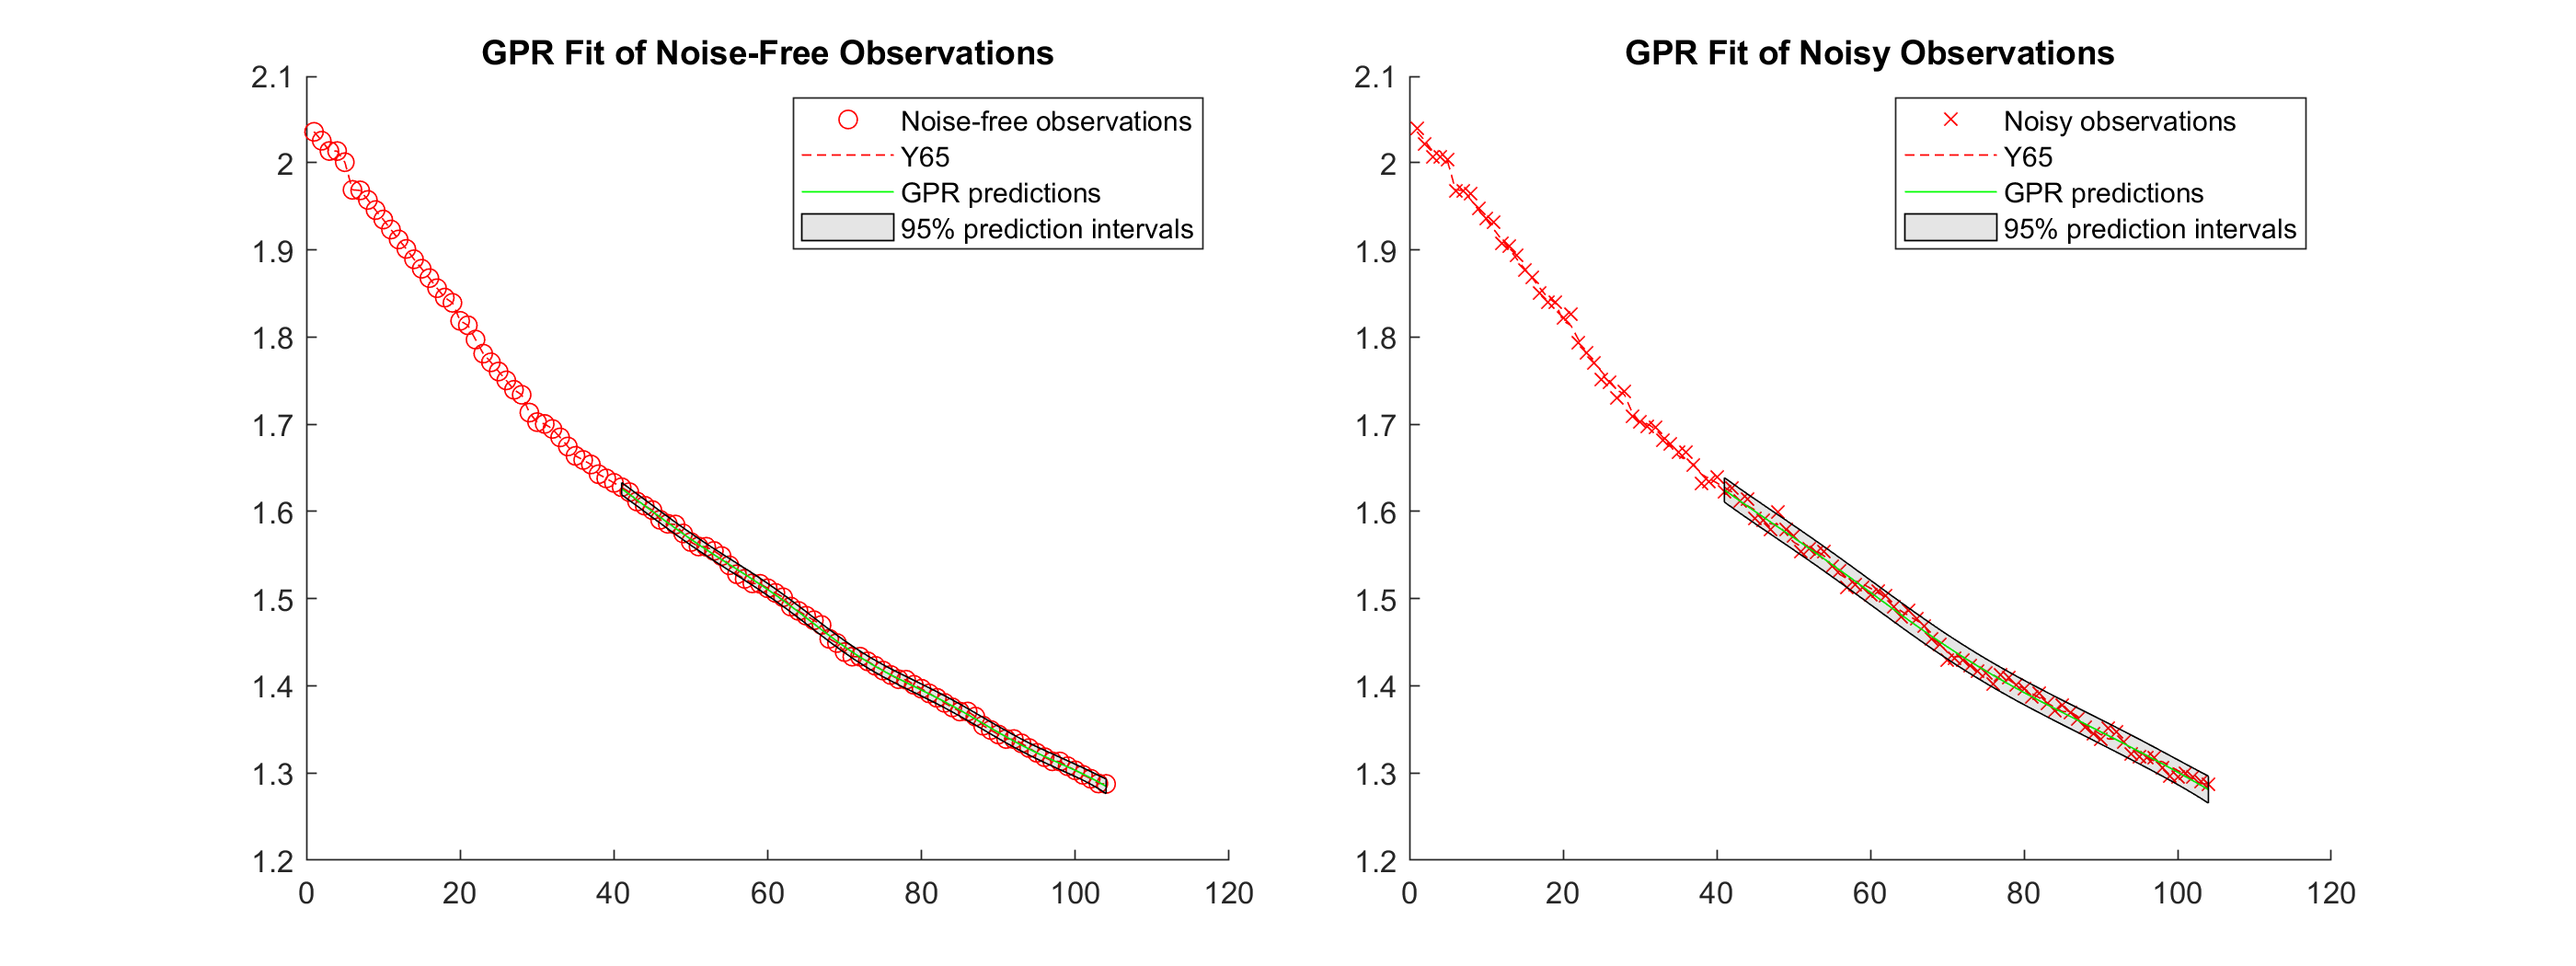

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;



%learning_start_index = 1;
learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = false;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

if use_just_observed
    % 변화된 구간 조금만 훈력
    x_observed = idxpre';
    y_observed1 =  BAT(idxpre);    
else
    % 모든 구간에 대해 훈련
    x_observed = idxall';
    y_observed1 =  BAT(idxall);   
end

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
%}

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );


[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

GP는 관측값이 작은 경우에서 큰 경우로 변경되면서 예측력이 우수해진다.  => 베이지안 기반 가우시안 프로세스

작은 관측값으로 먼저 피팅하고 새 관측값을 추가해보자.

1 6 11 16 22 26 31 36 41

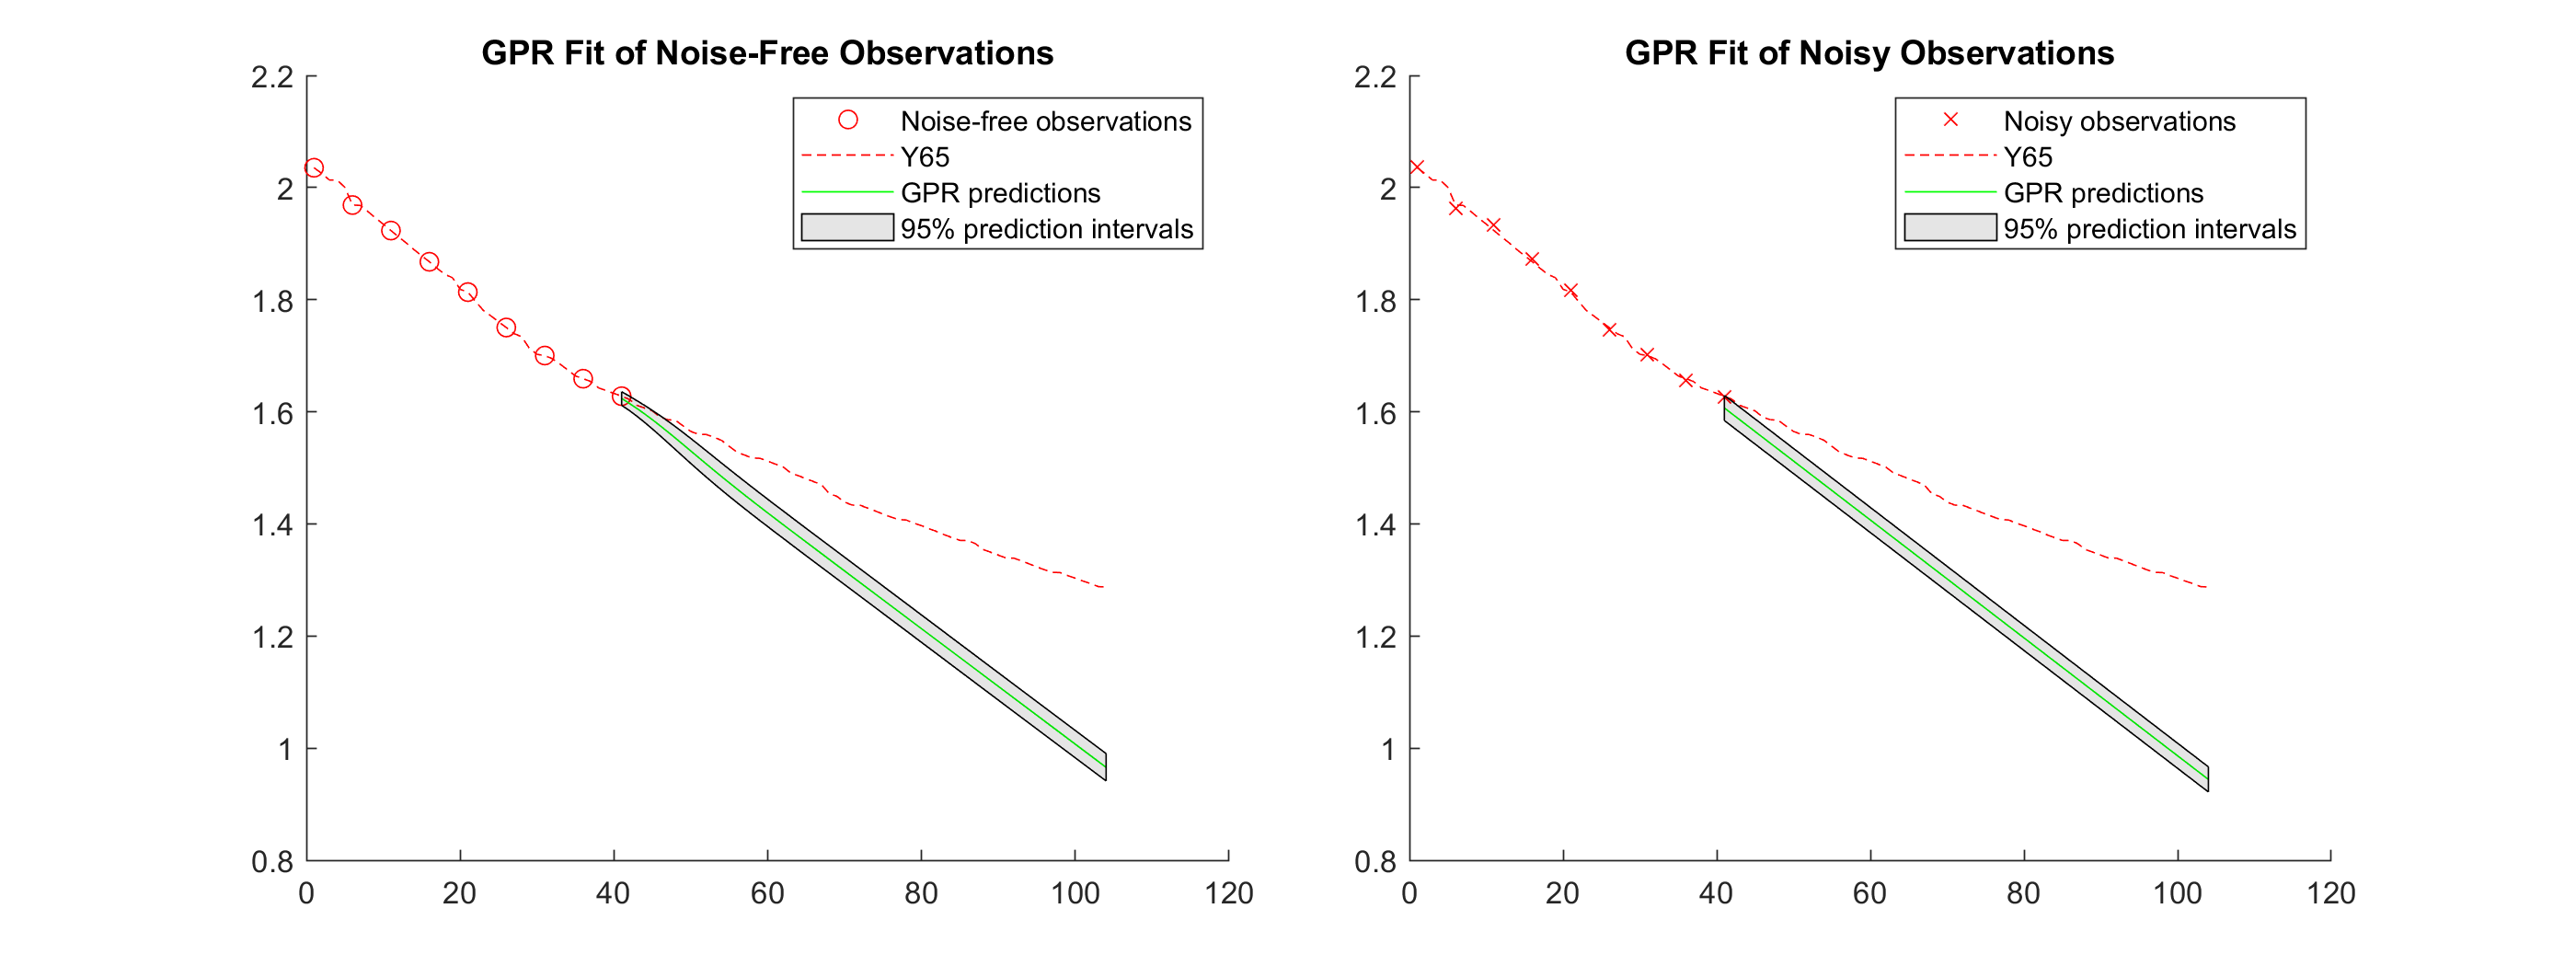

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;
BAT_sample = BAT(1:5:end); %21
%x_sample = [1:5:length(BAT)];
x_sample = [1:5:41]; % 41 51 61

learning_start_index = 1;
%learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = false;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

    x_observed = x_sample';
    y_observed1 =  BAT(x_sample);    

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

%}
gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );


[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

GP는 관측값이 작은 경우에서 큰 경우로 변경되면서 예측력이 우수해진다.  => 베이지안 기반 가우시안 프로세스

작은 관측값으로 먼저 피팅하고 새 관측값을 추가해보자.

변경된 시점부터 다시 시작한다.

31 36 41

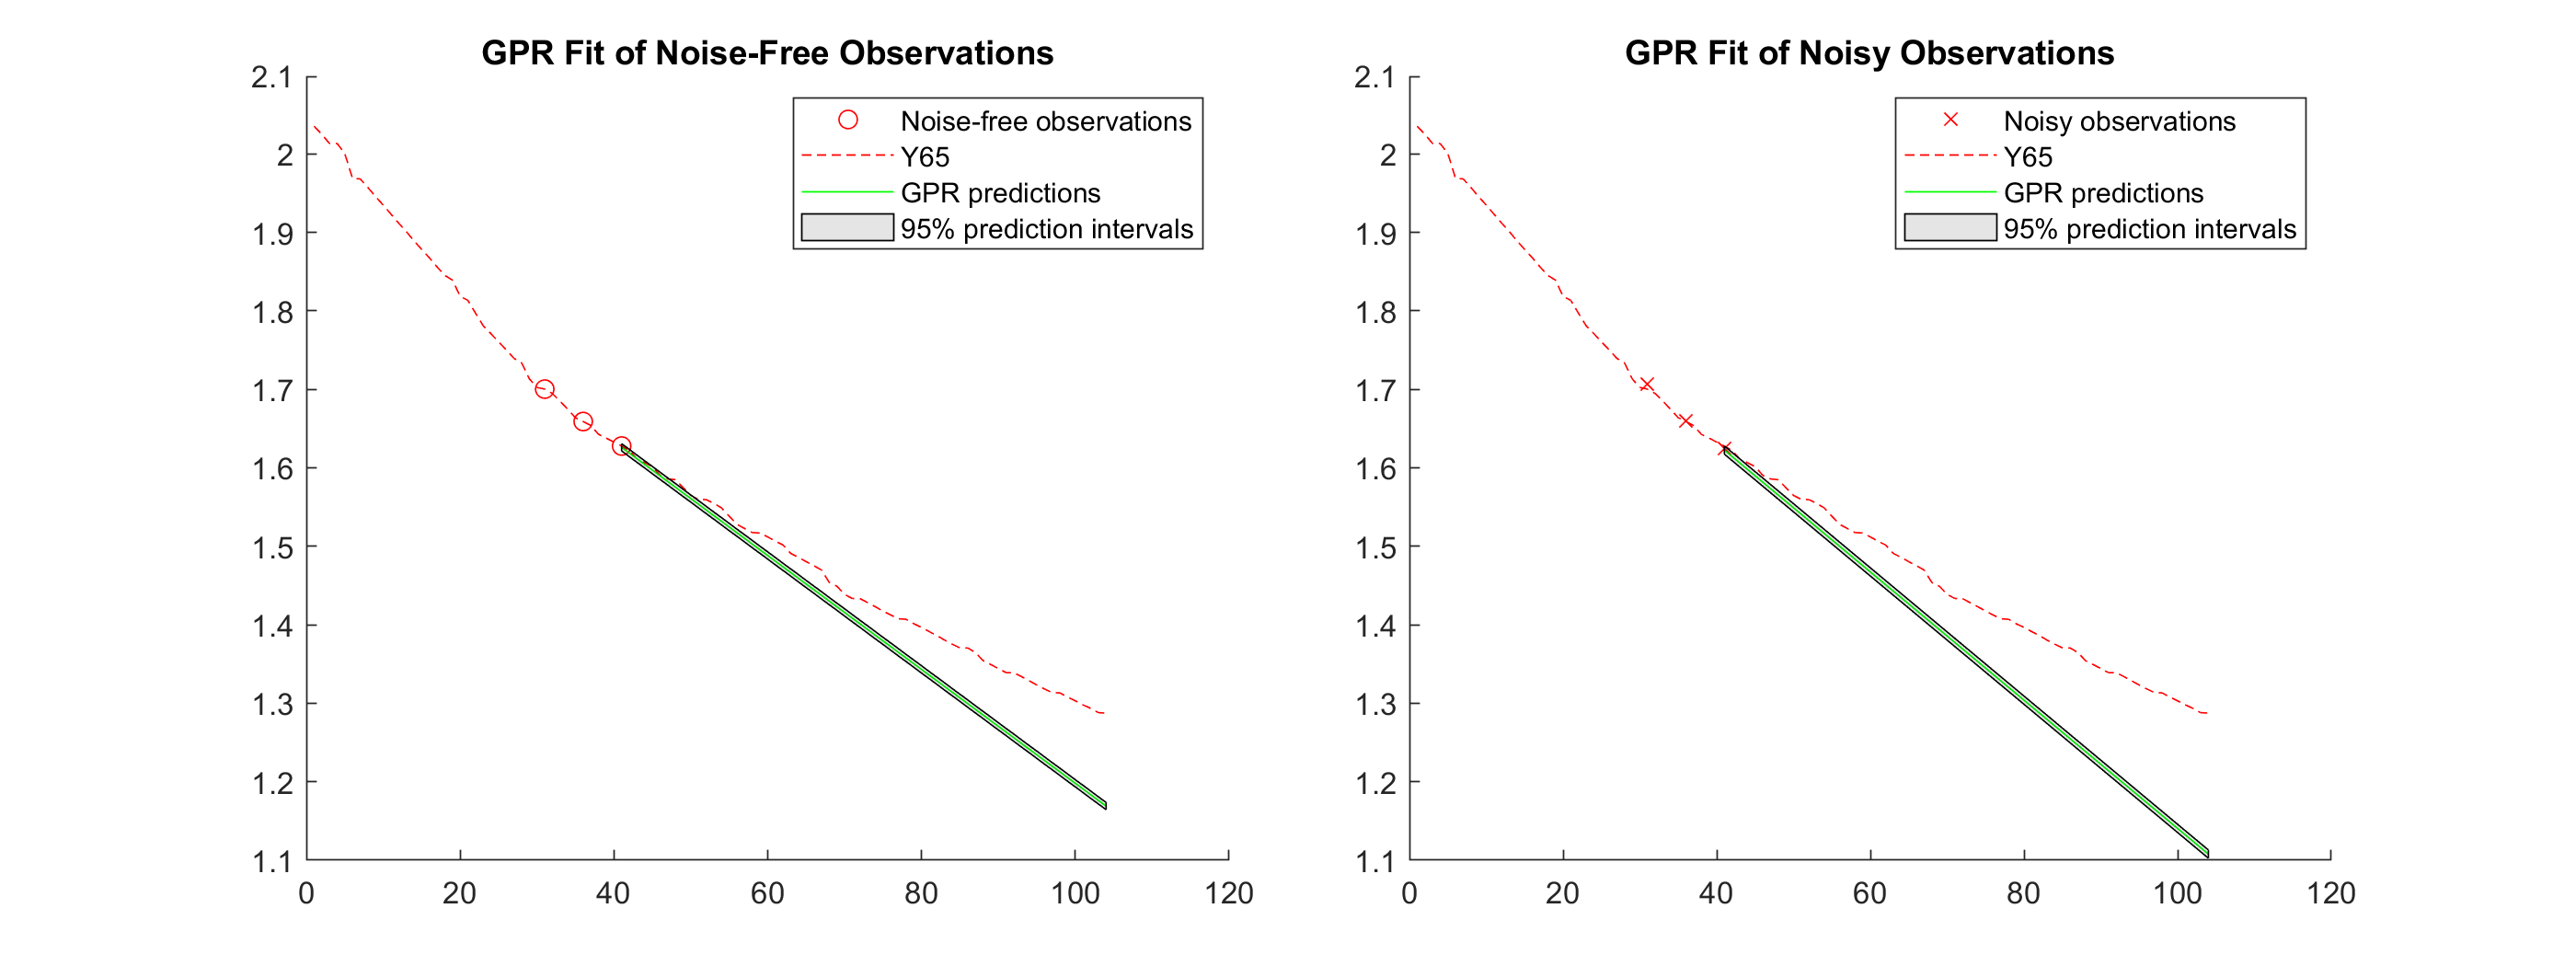

BAT = Y65;
BAT_NAME = 'Y65';
pattern_change_index =30;
BAT_sample = BAT(1:5:end); %21
%x_sample = [1:5:length(BAT)];
x_sample = [31 36 41]; % 41 51 61

learning_start_index = 1;
%learning_start_index = pattern_change_index; % 1;
learning_end_index = pattern_change_index + 10 ; % training addinonal 10 point after patten change 


%fit_param = ["KernelFunction" "squaredexponential" "FitMethod" "sr" "PredictMethod" "fic" "Standardize" 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 ];
%fit_param = ["KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" ];

use_just_observed = false;

%%%%%%%%%%%%%%%%%555

est_length = length( BAT) - learning_end_index;
end_index = length( BAT);

idxpre = learning_start_index:learning_end_index;
idxest = (learning_end_index+1):end_index;
idxall = 1:end_index;
 

    x_observed = x_sample';
    y_observed1 =  BAT(x_sample);    

y_observed2 = y_observed1 + 0.005*randn(size(x_observed));

%{
gprMdl1 = fitrgp(x_observed,y_observed1);
gprMdl2 = fitrgp(x_observed,y_observed2);

gprMdl1 = fitrgp(x_observed,y_observed1,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","constant","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","pureQuadratic","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );

%}
gprMdl1 = fitrgp(x_observed,y_observed1,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );
gprMdl2 = fitrgp(x_observed,y_observed2,"BasisFunction","linear","KernelFunction" , "squaredexponential" , "FitMethod" , "sr" , "PredictMethod" , "fic" , "Standardize" , 1 );


[ypred1,~,yint1] = predict(gprMdl1,idxest');
[ypred2,~,yint2] = predict(gprMdl2,idxest');

fig = figure;
fig.Position(3) = fig.Position(3)*2;
tiledlayout(1,2,'TileSpacing','compact')
nexttile
hold on
scatter(x_observed,y_observed1,'r') % Observed data points
%fplot(@(x) x.*sin(x),[0,10],'--r')  % Function plot of x*sin(x)
plot(idxall', BAT,'--r')
plot(idxest',ypred1,'g')                  % GPR predictions
patch([idxest';flipud(idxest')],[yint1(:,1);flipud(yint1(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noise-Free Observations')
legend({'Noise-free observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')

nexttile
hold on
scatter(x_observed,y_observed2,'xr') % Observed data points
plot(idxall',BAT,'--r')
plot(idxest',ypred2,'g')                  % GPR predictions                  % GPR predictions
patch([idxest';flipud(idxest')],[yint2(:,1);flipud(yint2(:,2))],'k','FaceAlpha',0.1); % Prediction intervals
hold off
title('GPR Fit of Noisy Observations')
legend({'Noisy observations',BAT_NAME,'GPR predictions','95% prediction intervals'},'Location','best')